# Save all figures into PDF

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

TargetPath = [FigurePath '/Demo043021/'];

% Go to the target folder and list all figures
cd(TargetPath)
listing = dir('*.fig');

## open and print

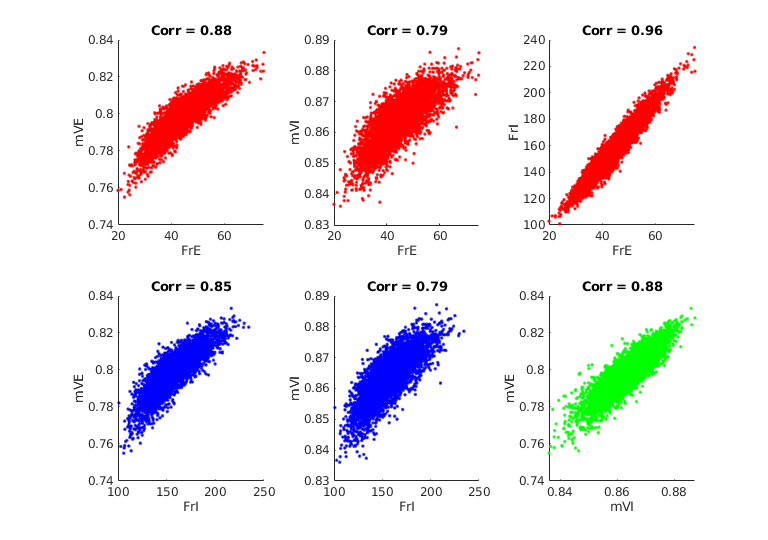

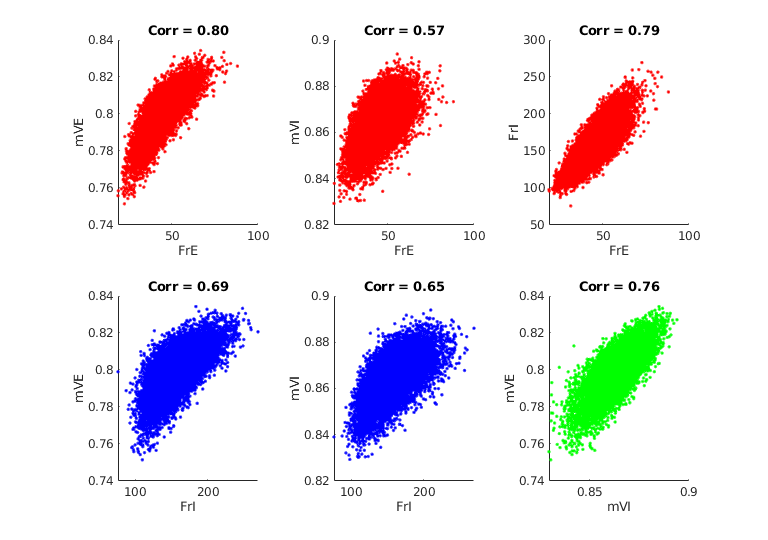

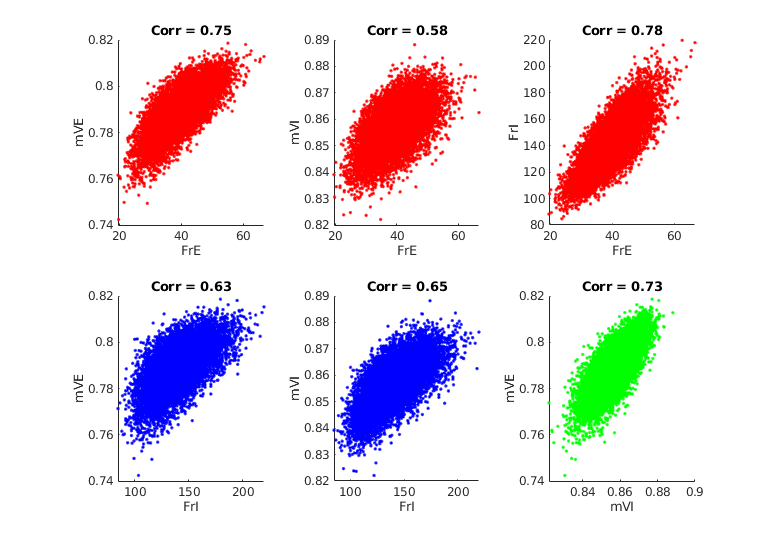

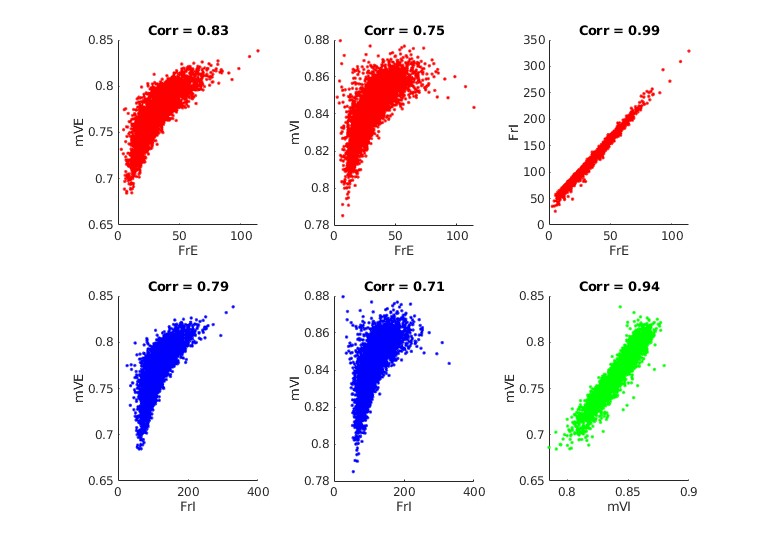

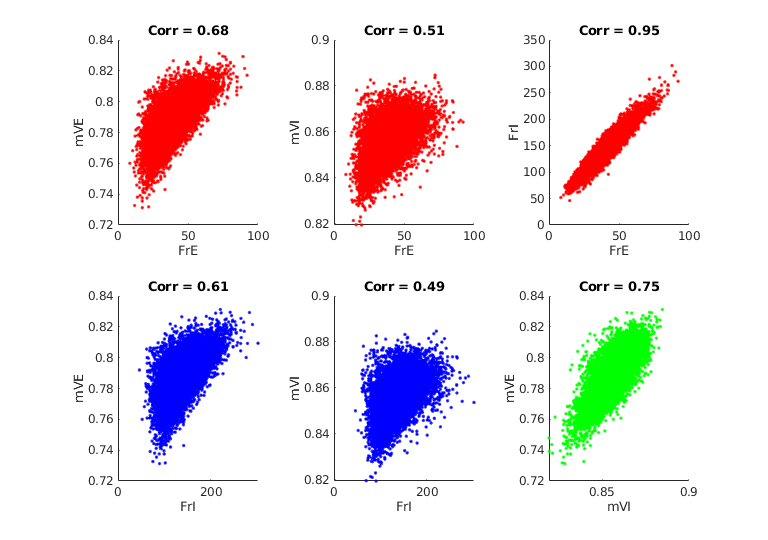

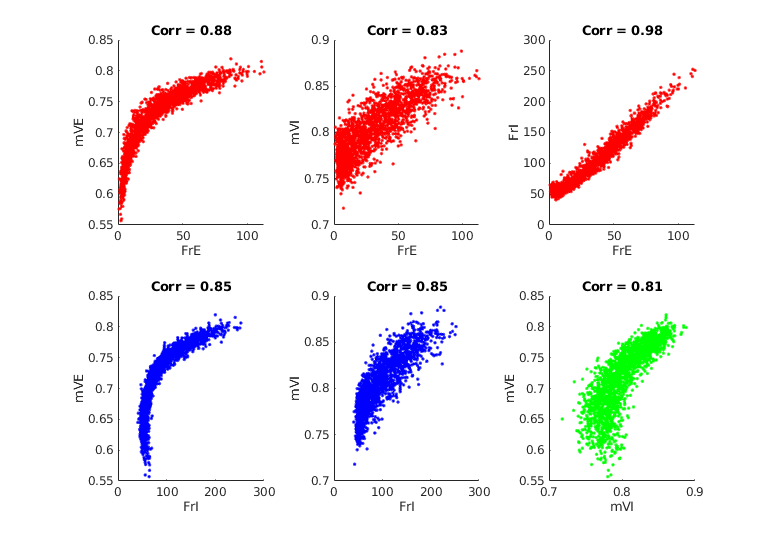

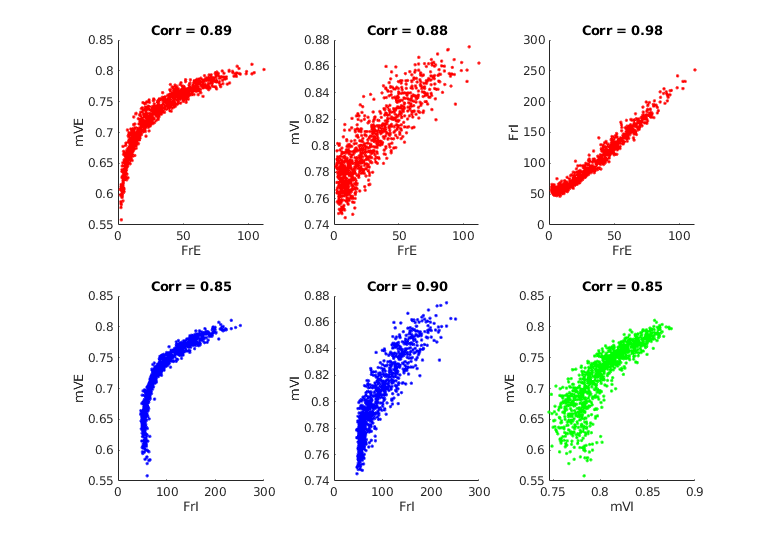

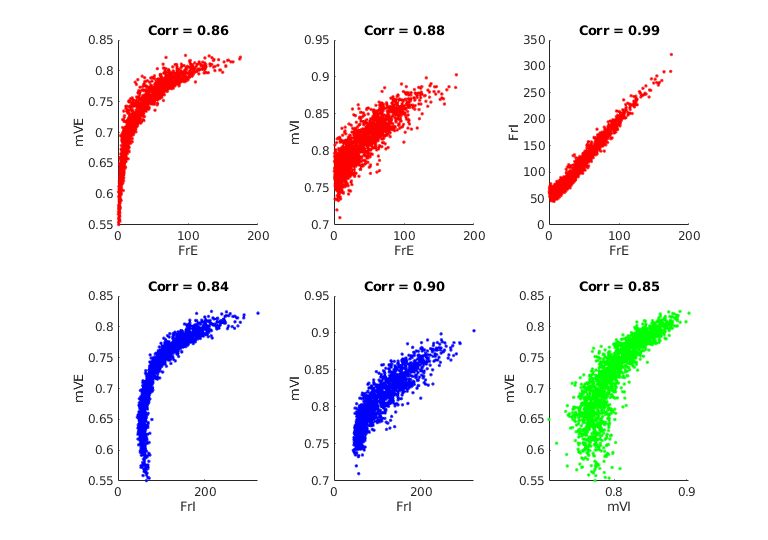

for FileInd = 1:length(listing)
    FileName = listing(FileInd).name;
    [~,name,extract]  = fileparts(FileName);
    hFig = openfig(FileName);
    set(hFig,'Units','normalized','Position',[0 0 0.2 0.5])
    exportgraphics(hFig,[name '.pdf'],'Resolution',300)
    
    close(hFig)
end